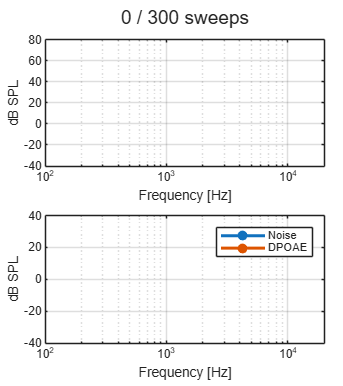

%% BY USING THIS SCRIPT, YOU ACCEPT THE FOLLOWING TERMS
%
% This script provides the basic underlying framework for measuring
% pure-tone distortion-product otoacoustic emissions (DPOAE) using the
% Titan Research Platform. The script supports the standard 2f1-f2
% protocol.
%
% This script is provided to illustrate the functionality of the Titan
% Research Platform. Interacoustics cannot aid the modification of the
% script to serve specific research needs, and such modification and the
% general use of the script is at your own responsibility.
%
% (c) Interacoustics A/S, Kren Monrad Noergaard, version 1.1, January 2025.

clear

addpath(genpath('../Research-dependencies/'))

fs=44100;
Titan=Titan(fs);

load('TransducerSensIOWA')

%% Settings
ch=[1 2];
blockLength=4096;
filterCutOff=250;
filterOrder=2;

dBSPL=[65 55];
dBmaxSweepNoise=55;
dBOAEpassSNR=15;
fRatio=1.22;

frequencyAim = load("dpFrequencies.mat");
f2aim = frequencyAim.f2aim;
f2Idx = frequencyAim.f2Idx;
minSweeps=25;
maxSweeps=300;

%% Initialize
t=(0:blockLength-1).'/fs;
freqFFT=(0:blockLength/2-1).'*fs/blockLength;
fftScale=2/(sqrt(2)*blockLength);
micSens=ppval(ppMicSens,freqFFT);

pTarget=2e-5*10.^(dBSPL/20);

[bFilter,aFilter]=butter(filterOrder,filterCutOff*2/fs,'high');
Hfilter=freqz(bFilter,aFilter,blockLength/2,fs);

% idxFreq=round((f2aim*blockLength/fs+1).*[1/fRatio 1]);
% idxFreq(:,3)=2*idxFreq(:,1)-idxFreq(:,2);
% freq=reshape(freqFFT(idxFreq),size(idxFreq));

%% Plots
fig=figure('units','normalized','outerposition',[0.3 0.1 0.4 0.8]);
tiledlayout(2,1,'padding','compact','tilespacing','compact')
sgtitle(fig,['0 / ' num2str(maxSweeps) ' sweeps']);

nexttile
lnSpectrum=semilogx(1,'linewidth',2);hold on
lnDPmarker=semilogx(1,'.','markersize',20);
xlim([100 20000]);ylim([-40 80])
xlabel('Frequency [Hz]');ylabel('dB SPL')
grid

nexttile
lnDPgramNoise=semilogx(0,'.-','markersize',20,'linewidth',2);hold on
lnDPgram=semilogx(0,'.-','markersize',20,'linewidth',2);
xlim([100 20000]);ylim([-40 40])
xlabel('Frequency [Hz]');ylabel('dB SPL')
legend('Noise','DPOAE')
grid

drawnow

%% Measurement
Titan.InitializePressure();

for nFreq=1:size(f2Idx,1)
    f2IdxVec = f2Idx(nFreq,:);
    f2IdxVec = f2IdxVec(f2IdxVec~=0);

    idxFreq = round((f2aim(f2IdxVec,1)*blockLength/fs+1).*[1/fRatio 1]);
    idxFreq(:,3)=2*idxFreq(:,1)-idxFreq(:,2);
    freq=reshape(freqFFT(idxFreq),size(idxFreq));

    stimulus(:,:,nFreq) = generateStimulus(1:length(f2IdxVec), freq, t);

    idxNoise = [];
    for i = 1:length(f2IdxVec)
        idxNoise = [idxNoise, round(idxFreq(i,3).^2./idxFreq(i,1))+1:idxFreq(i,3)-1, idxFreq(i,3)+1:idxFreq(i,1)-1];
    end
 
    % Adjust level
    spkrSens=[ppval(ppSpkrSens(ch(1)),freq(nFreq,1)) ppval(ppSpkrSens(ch(2)),freq(nFreq,2))];
    levelStart=pTarget./abs(spkrSens);
    Titan.StartStimulation(sqrt(2)*levelStart.*stimulus(:,:,nFreq),ch);
    Titan.LogResponses(2);

    [~,initFilter]=filter(bFilter,aFilter,Titan.response{end}(:,1));
    [responseAdjust,initFilter]=filter(bFilter,aFilter,Titan.response{end}(:,2),initFilter);
    fftResponseAdjust=fftScale*dft(responseAdjust)./(Hfilter.*micSens);
    level=levelStart.*pTarget./abs(fftResponseAdjust(idxFreq(nFreq,1:2))).';
    % if max(dbspl(spkrSens.*level))>90
    %     error('Pressure threshold exceeded.')
    % end

    % Measure DPOAE
    Titan.StartStimulation(sqrt(2)*level.*stimulus(:,:,nFreq),ch);
    Titan.StartLogging();

    nBlock=1;
    nSweep=1;
    while 1
        Titan.Wait(nBlock)

        response{nFreq}(:,nBlock)=Titan.response{end}(:,nBlock);
        if nBlock==1
            [~,initFilter]=filter(bFilter,aFilter,response{nFreq}(:,nBlock));
        else
            [responseFiltTmp(:,mod(nBlock,2)+1),initFilter]=filter(bFilter,aFilter,response{nFreq}(:,nBlock),initFilter);
            if mod(nBlock,2)
                fftResponseNoise=dft(responseFiltTmp);
                rmsSweepNoise=sqrt(2/blockLength^2*sum(abs(diff(fftResponseNoise(2:end,:),1,2)./sqrt(2)./(micSens(2:end))).^2));
                if dbspl(rmsSweepNoise)>dBmaxSweepNoise
                    nBlock=nBlock+1;
                    continue
                end

                meanResponseFilt{nFreq}(:,nSweep)=mean(responseFiltTmp,2);
                fftResponse(:,nFreq)=fftScale*dft(mean(meanResponseFilt{nFreq},2))./(Hfilter.*micSens);

                dpResponse(:,nFreq)=fftResponse(idxFreq(nFreq,3),nFreq);
                noiseFloor(:,nFreq)=mean(abs(fftResponse(idxNoise,nFreq)));

                set(lnSpectrum,'xdata',freqFFT,'ydata',dbspl(fftResponse(:,nFreq)));
                set(lnDPmarker,'xdata',freqFFT(idxFreq(nFreq,3)),'ydata',dbspl(fftResponse(idxFreq(nFreq,3),nFreq)));
                set(lnDPgram,'xdata',freq(1:nFreq,2),'ydata',dbspl(dpResponse))
                set(lnDPgramNoise,'xdata',freq(1:nFreq,2),'ydata',dbspl(noiseFloor))
                sgtitle(fig,[num2str(nSweep) ' / ' num2str(maxSweeps) ' sweeps'])
                drawnow limitrate

                if (db(dpResponse(:,nFreq))-db(noiseFloor(:,nFreq))>dBOAEpassSNR && nSweep>=minSweeps) || nSweep>=maxSweeps
                    break
                end
                nSweep=nSweep+1;
            end
        end
        nBlock=nBlock+1;
    end
end
Titan.StopLogging();
Titan.StopInstrument();

%% Save
timestamp=datetime('now');
save(['Measurement/dpoaeMeas' char(datetime(timestamp,'format','yyMMdd_HHmmss'))],...
    'response','meanResponseFilt','fftResponse','dpResponse','noiseFloor',...
    'dBSPL','level','fRatio','idxFreq','freq','freqFFT','blockLength',...
    'micSens','stimulus','fs','ch','bFilter','aFilter','Hfilter','timestamp')
